# Effects of negative feedback

This file serves as an introduction to the beneficial effects of feedback through a range of different scenarios; in essence why is feedback useful? Specifically the file provides some analyses of some properties of negative feedback applied in control of a variety of systems. Besides demonstrating reference signal tracking, disturbance and noise rejection properties of negative feedback, stability issues are also demonstrated and some beneficial properties as linearising of nonlinear characteristics are also shown. 

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx ***and ***step_responses_with_matlab.mlx.***

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars and László Keviczky,                        and J.A.Rossiter, University of Sheffield

Budapest University of Technology and Economics                                                 

                                 

## Table of contents

- Control in open- and in closed-loop

- Feedback with systems with challenging dynamics

- Feedback may improve the transient response

- Feedback has a linearising effect

- Summary

## 1. Control in open- and in closed-loop

The aim of a control system is to ensure reference signal tracking as well as disturbance rejection. The control system has to be not very sensitive to measurement noises and to plant/model mismatch.

The control system has to ensure several quality specifications (as stability, static accuracy, properties of transient response, etc.). Also its design has to be technically realisable and consider economical and other (e.g. environmental protection and safety) viewpoints. 

In the figure 1.1 below *G(s)* is the transfer function of the plant. Disturbances $y_{\textrm{no}} ,y_{\textrm{ni}}$ are applied at both the output and the input of the plant respectively. *M(s)* is the transfer function of the controller. *r* denotes the reference signal, *y* is the output signal.

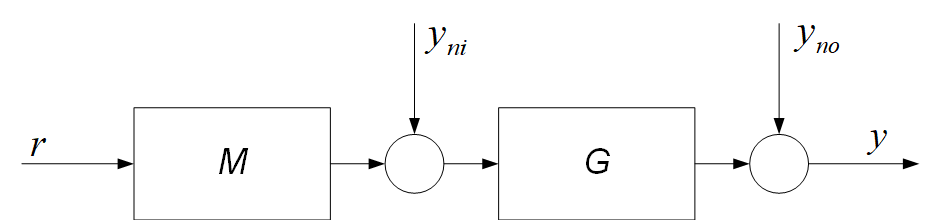

**Figure 1.1**: *Block diagram representation of forward path and disturbances*

### 1.1 Open-loop designs for tracking

Reference signal tracking would be ideal if the controller could realise the inverse of the transfer function of the plant, as shown in figure 1.2 below.

                               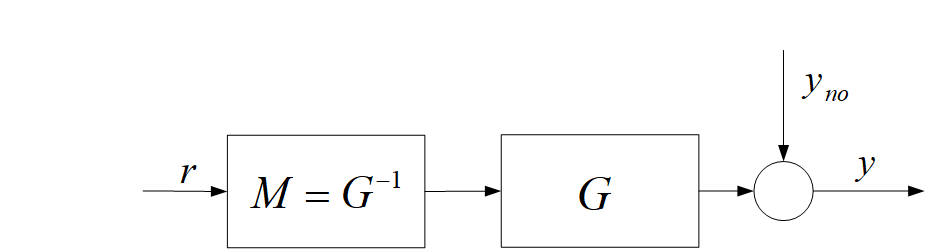

**Figure 1.2**: *Ideal tracking using a model inverse* 

Generally this compensator is physically non realisable and indeed, the model is only an approximation of reality so this would inevitably lead to some errors regardless. In some cases, the inverse of the process transfer function could be approximated by a high gain amplifier fed back by the transfer function of the model of the plant as shown in Figure 1.3 below.

       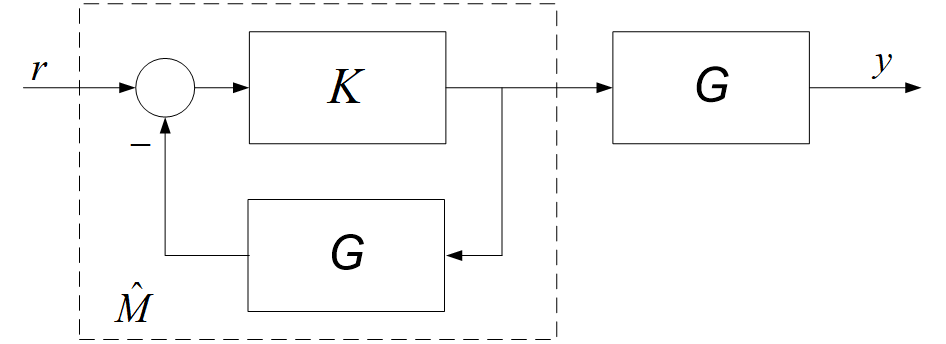

**Figure 1.3**: *Approximation of a model inverse using feedback *

The gain of the amplifier is *K*. The transfer function of the controller is


$$M\left(s\right)=\frac{K}{1+\textrm{KG}\left(s\right)}=\frac{1}{G\left(s\right)+\frac{1}{K}}\simeq \frac{1}{G\left(s\right)}$$


which approximates the inverse of the transfer function of the plant if the gain *K* is very high, and of course, assuming that this loop is stable! Nevertheless, this control design has an open loop structure which, while it may track the reference signal fairly well in the nominal case (no parameter uncertainty), it is most definitely unable to reject the effect of the disturbances and thus would be unacceptable in general.

### 1.2 Closed-loop designs for tracking and disturbance rejection

The figure below shows an equivalent closed loop block diagram which is also able to reject the effect of the disturbances, but of course the tracking is not as precise as would be delivered by the unrealistic designs in section 1.1. 

                              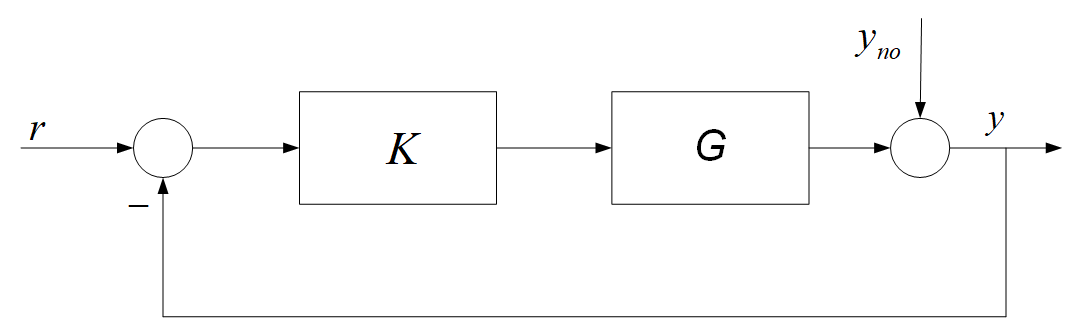

**Figure 1.4**: *A closed-loop control implementation *

Instead of a pure high gain appropriately designed controllers can ensure asymptotic reference signal tracking and disturbance rejection in closed loop as shown in the next figure. Whatever effect is causing the deviation of the output signal from its desired value, the error signal will be different of zero creating a control signal which works to eliminate the deviation. The effect of the measurement noise can also be attenuated. 

Design of common controllers is discussed in other toolbox files:

***proportional_design_with_bode.mlx, lag_design_with_bode.mlx, lead_design_with_bode.mlx, lead_lag_design_with_bode_toolbox.mlx, PID_Cont_Controller_Design_with_Pole_Cancellation.mlx, PID_tuning_methods_toolbox.mlx***

Figure 1.5 shows a more complete block diagram which can be used to determine the input and output behaviours and their dependence on the various loop inputs: besides the input and output disturbances the measurement noise $y_{z\;}$is also shown in the figure. Filter *F* could modify the reference signal.

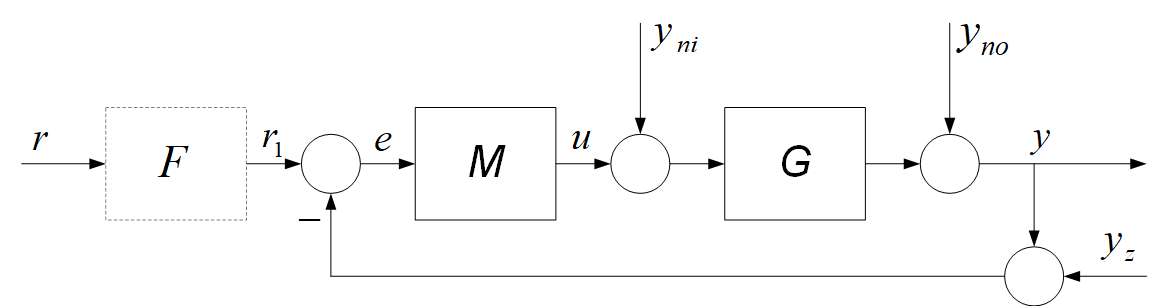

**Figure 1.5**: *A closed-loop control implementation showing various loop input signals *

The relationships between the Laplace transforms of the outputs (*y*,  *u*  and  *e*  and the inputs (*r*,  $y_{\textrm{ni}}$,  $y_{\textrm{no}}$  and $y_z$ )  applying the superposition principle are:


$$y\left(s\right)=F\left(s\right)\frac{M\left(s\right)G\left(s\right)}{1+M\left(s\right)G\left(s\right)}r\left(s\right)+\frac{G\left(s\right)}{1+M\left(s\right)G\left(s\right)}y_{\textrm{ni}} \left(s\right)+\frac{1}{1+M\left(s\right)G\left(s\right)}y_{\textrm{no}} \left(s\right)-\frac{M\left(s\right)G\left(s\right)}{1+M\left(s\right)G\left(s\right)}y_z \left(s\right)$$



$$u\left(s\right)=F\left(s\right)\frac{M\left(s\right)}{1+M\left(s\right)G\left(s\right)}r\left(s\right)-\frac{M\left(s\right)G\left(s\right)}{1+M\left(s\right)G\left(s\right)}y_{\textrm{ni}} \left(s\right)-\frac{M\left(s\right)}{1+M\left(s\right)G\left(s\right)}y_{\textrm{no}} \left(s\right)-\frac{M\left(s\right)}{1+M\left(s\right)G\left(s\right)}y_z \left(s\right)$$



$$e\left(s\right)=F\left(s\right)\frac{1}{1+M\left(s\right)G\left(s\right)}r\left(s\right)-\frac{G\left(s\right)}{1+M\left(s\right)G\left(s\right)}y_{\textrm{ni}} \left(s\right)-\frac{1}{1+M\left(s\right)G\left(s\right)}y_{\textrm{no}} \left(s\right)-\frac{1}{1+M\left(s\right)G\left(s\right)}y_z \left(s\right)$$


The closed loop control system has to track the reference signal (asymptotically) and to decrease the effect of the input and output disturbances and also reject the effect of the measurement noise. The controller *M(s)* also has to be designed to meet the quality specifications set for the static and dynamic behaviour of the control system (for example,  if *G* is a lag element and *M* is a constant gain, then for a step reference signal $r_1$ there will be a steady state error in signal y. If M contains an integrator, then the steady state error will be zero.)

### 1.3 Numerical example

The following example demonstrates the effect of feedback. The model of the plant is given by its transfer function. 

$G\left(s\right)=\frac{2}{1+10s}$. 

The effect of two controllers is examined.

$M_1 \left(s\right)=5$  and $M_2 \left(s\right)=5\frac{1+10s}{10s}$.

The filter is F=1 and the disturbances are unit steps.

Calculate and plot the output signal, the control signal and the error signal for the  reference signal, for the input and the output disturbances with the given controllers. It is noted that:

- The closed loop is much faster than the plant.

- With proportional controller there is a static error. 

- The overexcitation in the control signal accelerates the response.

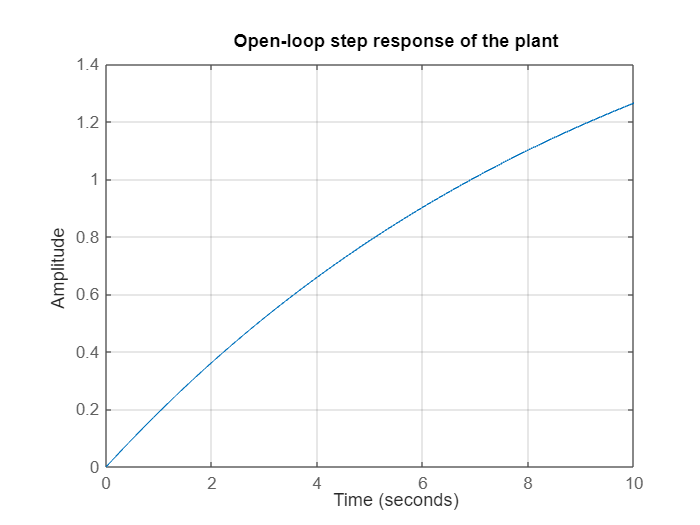

s=tf('s');
G=2/(1+10*s);
F=tf(1,1);
M1=5;
M2=5*(1+10*s)/(10*s);
L1=M1*G;
L2=minreal(M2*G,0.001);
t=0:0.1:10;
step(t,G),grid
title('Open-loop step response of the plant')

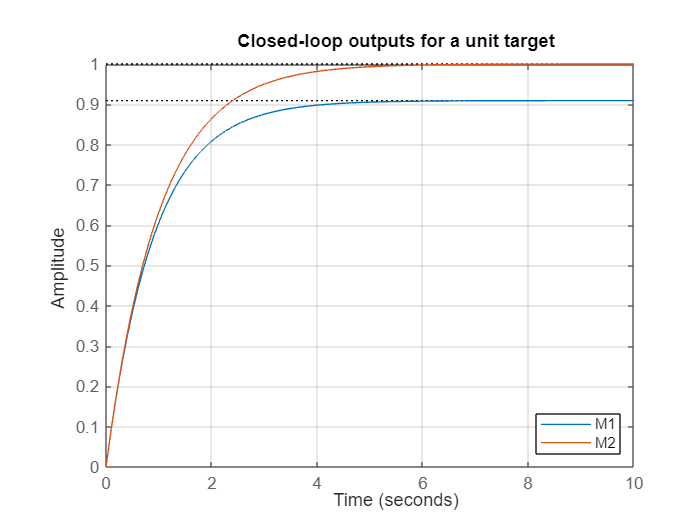



T1=feedback(L1,1);
T2=feedback(L2,1);
step(t,T1,t,T2),grid
title('Closed-loop outputs for a unit target')
legend('M1','M2','Location','Southeast')

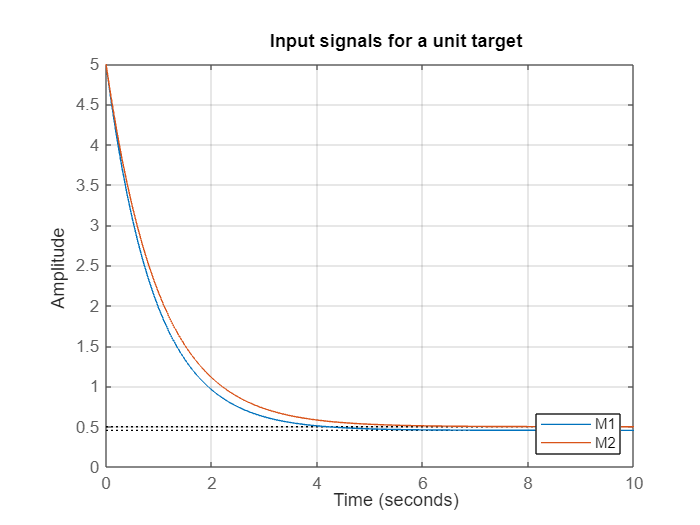



U1=feedback(M1,G); 
U2=feedback(M2,G); 
step(t,U1,t,U2),grid
title('Input signals for a unit target')
legend('M1','M2','Location','Southeast')

Rather than computing numerous closed-loop transfer functions given in section 1.2, it can be easier to use tools such as simulink (see file ***simulink_general_structure_control101.slx***) to explore the impact of input and output disturbances. In this example, there are:

- an input disturbance of 0.5 after 10 seconds.

- an output disturbance of 0.5 after 20 seconds.

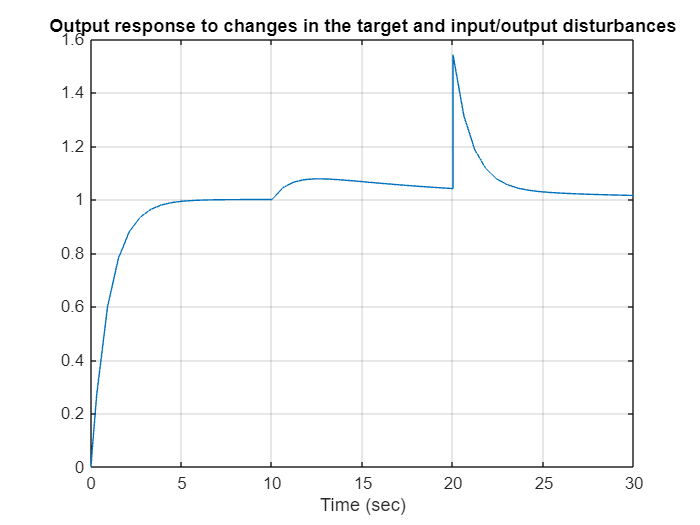

% Run the Simulink simulation with the second (PI) controller M2.
endtime=30;
Data=sim('simulink_general_structure_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;

% Plotting
plot(t,y),grid
title('Output response to changes in the target and input/output disturbances')
xlabel('Time (sec)')

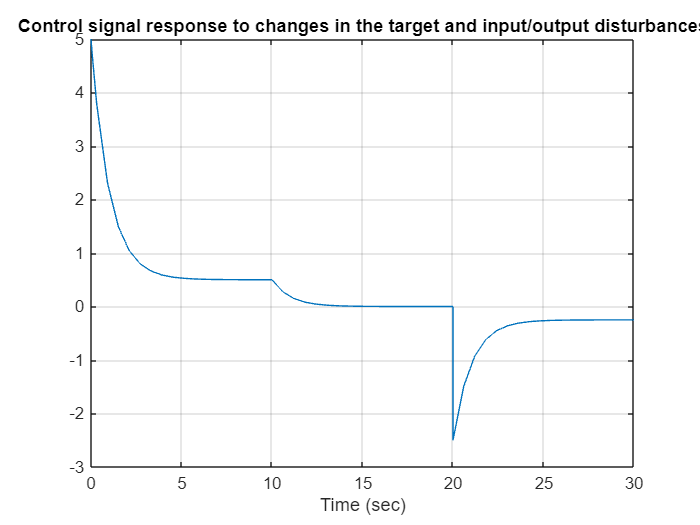

plot(t,u),grid  
title('Control signal response to changes in the target and input/output disturbances')
xlabel('Time (sec)')

It is seen that after settling of the transients the output follows the reference signal and rejects the effects of the input and of the output disturbances.

**STUDENT TASK**: choose other plants and other controllers and evaluate the behaviour of the control system.

## 2.Feedback with systems with challenging dynamics

A basic requirement set for a control system is stable behaviour, which means that for a finite change in the input signal the control system should respond with a finite change in the output signal, i.e. a steady state should be reached. 

Open loop control systems should be stable by design and can only be used if the process itself is stable. But for a good performance a quite accurate knowledge of the system is required. An open loop control system can follow the reference signal (assuming an accurate model), but can handle only a priori known disturbances. This section shows examples of how a simple feedback loop can significantly improve on the open-loop behaviour, but equally can make behaviour worse if chosen poorly.

In a closed loop control system realised by negative feedback, reference signal tracking and disturbance rejection can be reached, as whatever the effect, its impact is detected in the error signal and the feedback works to eliminate it. But because of the process dynamics this feedback process takes time to be effective. In a closed loop control system oscillations with steady or increasing amplitude may occur where the feedback is poorly designed. The reason for that is that the execution of the command to change the process output is delayed by the dynamics of the process.  High gains in the control system may increase the unfavourable change of the signals to such an extent that the control system will not be able to reach a steady state. This is particularly an issue when the system includes some challenging dynamics. Figures 2.1 demonstrate some of these processes.

- Big delays or big dead time in the process dynamics also may cause unstable behaviour in the control system. It is difficult to control processes with big dead time or to control unstable processes. As an example showering is a process with big a dead time, as the change in the hot or cold water flow is sensed only after going through the pipes, which means a dead time. 

- The juggler wants to balance a rod, which is also a difficult control process, as the process itself is unstable. 

                                             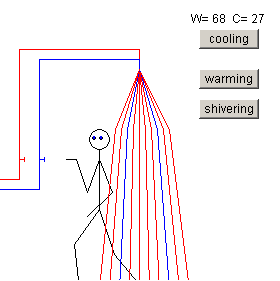                     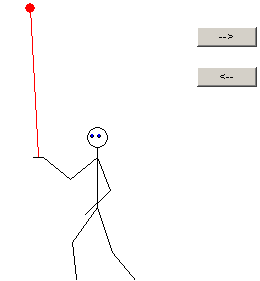

**Figure 2.1** *Processes with challenging open-loop dynamics*

### 2.1 Numerical illustration of proportional feedback and a delay

Analysis of stability is discussed in file ***stability_continuous.mlx***. Here the phenomenon is demonstrated through a closed loop control system where the process is characterised by a pure dead time $T_d$ and the controller is proportional with gain *K. *The block diagram of the closed loop control system is shown in the figure 2.2 below.

                                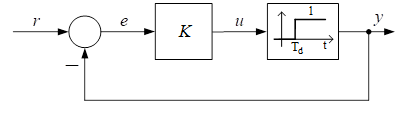

**                                                            Figure 2.2** *Simple loop with a delay*

The table below gives the first consecutive values of the error and the output signal.

It is seen that the course of the error signal is described by a geometric series with quotient -*K. *It is convergent if *K*<1, and converges to $\lim_{t\to \infty } \;e\left(t\right)=\frac{1}{1+K}$.  The higher the value of *K*, the smaller is the error. But in this case the maximum value of *K* is 1, the error tends to 0.5. So the static error will be big. Figure 2.3 below shows the error and the output signals of the control system in case of unit step reference signal. It is seen that stability and static accuracy are contradictory viewpoints in that increasing K reduces offset only until a limit of 50%, after which closed-loop instability results.

                                  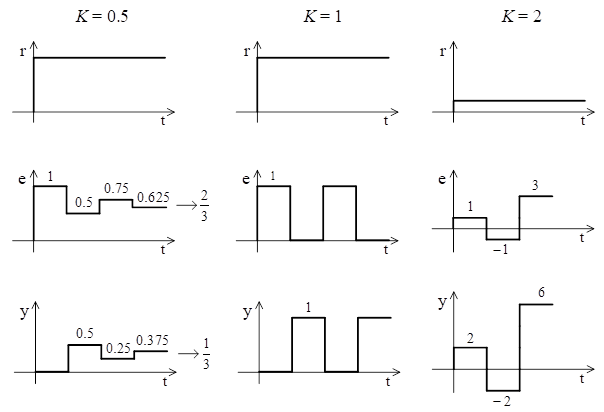

**                                    Figure 2.3** *Changes in closed-loop behaviour with changes in gain*

If instead of a proportional controller we use an integrator, in steady state the error should be zero, as for a constant output of the integrator its input, the error signal should be settled to zero. Of course in this case stability also should be ensured. 

**STUDENT TASK**: The code below shows the gain and phase margins and closed-loop behaviour of the system with integrator and dead time. Explore the behaviour with different values of gain and dead-time (the critical gain can be calculated by methods discussed in file ***stability_continuous.mlx)***.

display('Behaviour of a dead time system with integrator controller')
s=tf('s');
Td=1;   % The dead-time
K=0.5;  % Compensator gain
%K=pi/2     %This is the critical gain
L=K*exp(-Td*s)/s
margin(L),grid
t=0:0.1:10;
T=L/(1+L);
step(t,T),grid
title('Step response of a delay system with simple feedback')

**STUDENT TASK**: Build the SIMULINK systems shown in Figure 2.4  and investigate the behaviour of the systems with a constant and with an integrator controller. You could also explore the impact of adding dynamics into the system.

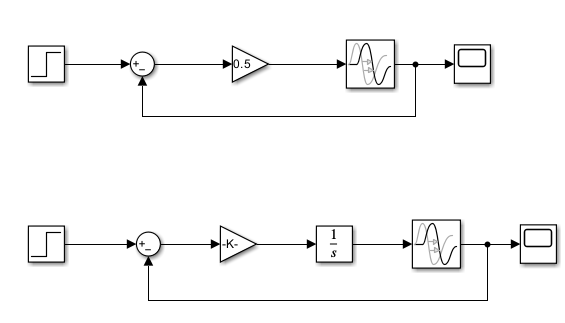

**Figure 2.4** *Simulink diagrams for feedback loops with a simple delay system*

### 2.2 Open-loop unstable systems

An unstable process can often be stabilised by negative feedback. As an example consider the simple 1st order system given below  whose transfer function has a positive pole (Figure 2.5). With appropriately chosen constant feedback the pole of the closed loop can be pushed to the left side of the complex plane.

                              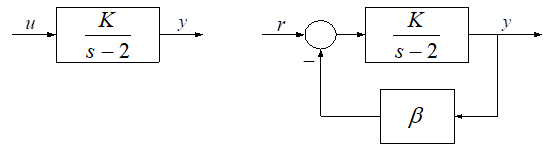

**                                Figure 2.5** Un unstable process can be stabilised by constant negative feedback

The transfer function of the closed loop is

$T\left(s\right)=\frac{\frac{K}{s-2}}{1+\beta \frac{K}{s-2}}=\frac{K}{s-2+\beta K}$.          The system is stable for any value of *K* satisfying $\beta K>2$.

**STUDENT TASK**: You could use the simulink file and code from section 1.3 to investigate this system behaviour, and also the efficacy of the control in rejecting disturbances. Simply update the definition of the transfer function models used in the file.

## 3. Feedback may improve the transient response

Let us consider some systems with relatively benign open-loop dynamics such as the first order lag element in  figure 3.1 below. 

                         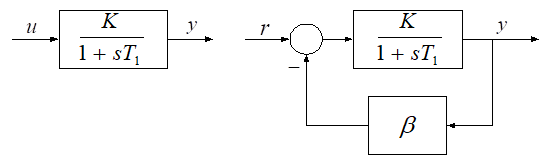

**                                        Figure 3.1** *Feedback loop with a 1st order system*

With the constant feedback the resulting closed-lopp transfer function is:


$$T\left(s\right)=\frac{Y\left(s\right)}{R\left(s\right)}=\frac{K}{1+\beta K}\;\frac{1}{1+s\frac{T_1 }{1+\beta K}}=\frac{\hat{K} }{1+s\hat{T_1 } }$$


The time constant has been decreased, so the system converges faster. At the same time the steady-state gain has also been decreased, what has to be compensated by using a filter. The core point here being that adding feedback changes behaviour (also see  ***firstordermodels_responses_analysis_and_feedback.mlx*** for more on this case).  Assuming one has some desired behaviour in mind, one can choose $\beta$ to get closer to that behaviour.         

As an example consider two serially connected lag elements, where $H_1 \left(s\right)=\frac{2}{1+10s}$ and $H_2 \left(s\right)=\frac{5}{1+5s}$. Without the constant feedbacks the overall transfer function is $H\left(s\right)=\frac{10}{\left(1+10s\right)\left(1+5s\right)}$. With constant feedback elements a=5  and  b=2 compare the step response of the system with the original uncompensated system. Compensate the static gain to ensure the same steady state value for the two systems.

                             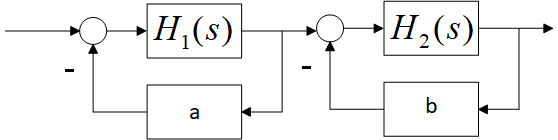

**         Figure 3.2** *Series arrangement of two simple feedback loop containing1st order systems*

display('Constant feedback accelerates the system.')
s=tf('s');
a=5;
b=2;
H1=2/(1+10*s);
H2=5/(1+5*s);
display('The original system with two time lags')
H12=H1*H2
disp('The feedback system With static compensation')
H=feedback(H1,a)*feedback(H2,b);
Hfb=H*dcgain(H12)/dcgain(H)    % Ensuring the same static gain

step(H12,Hfb),grid
title('The step responses of the open and closed-loop configurations')
legend('Open-loop','Closed-loop')

It is seen that with constant feedback of the lag elements the convergence became much faster.

## 4. Feedback has a linearising effect

A further useful property of feedback is that it can have a linearising affect on systems with significantly non-linear models, and this makes use of such systems easier. Let us consider the static nonlinear characteristics in figure 4.1 below. 

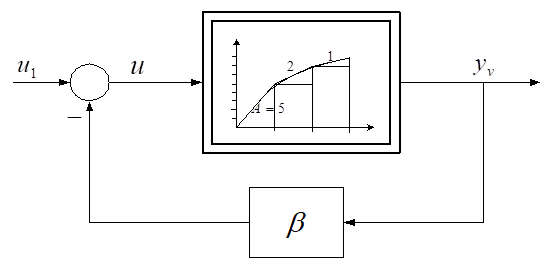 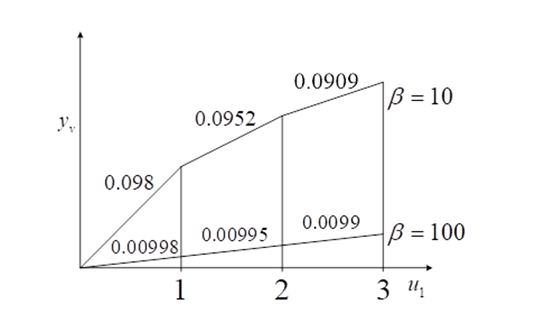

**Figure 4.1** *Simple feedback arrangement containing a non-linear element *

The characteristics can be divided into three linearised ranges, which are given by slope *A*. The feedback is a gain $\beta$. While the system remains entirely with a single linearised ranges the effective gain could be considered as a constant *A*, and therefore the closed-loop function would reduce to  the slopes  $\frac{A}{1+A\beta }$. In essence, if one stays within a single range, the characteristics can already be considered to be linear, but more significantly, the variation in gain as one moves from one range to another would be much smaller than in the open-loop case.

Control of linear systems is straightforward, while control of nonlinear systems is more difficult and requires special considerations. Therefore it is advantageous linearising the characteristics of the system before designing the control system. A simulink file has been built which contains a non-linear element $u^2$; its block diagram is shown on the figure 4.2 which compares the open-loop and closed-loop (with simple proportional feedback) behaviour of this system. Running the file it is seen that the inclusion of feedback really linearises the output.

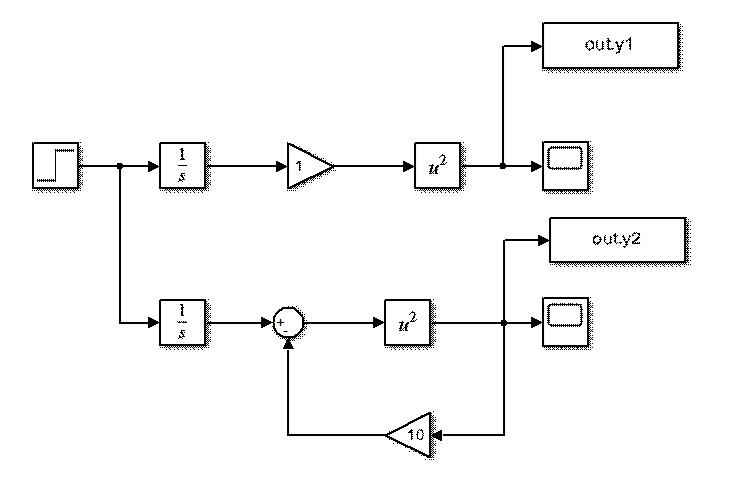

**Figure 4.2** *Illustration of the file fb_linearises_control101.slx*

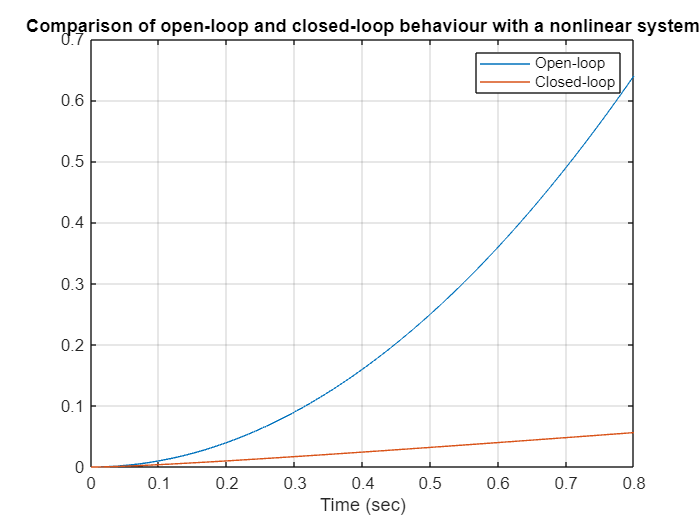

% Run the Simulink simulation 
endtime=0.8;
Data=sim('fb_linearises_control101.slx');
y1=Data.y1.signals.values;
y2=Data.y2.signals.values;
t = Data.y1.time;
% Plotting
plot(t,y1,t,y2),grid
title('Comparison of open-loop and closed-loop behaviour with a nonlinear system')
xlabel('Time (sec)')
legend('Open-loop','Closed-loop')

## **5. Summary** 

This livescript file has given a wide range of illustrations of the impact of feedback on behaviour and more specifically, the opportunity to influence and improve the behaviour of a system. This should serve as motivation for deeper studies of feedback systems which is supported through many files in the toolbox.

Measuring the output of the plant and comparing this information with its reference value provides an error signal which can be used to change the input of the system in order to reach the required behaviour of its output. Of course how to use the error signal to modify the input needs design considerations in order to meet the quality specifications set for the control system, and thus the need for study of systematic design approaches.